## **Plots processed data from phase field model in single pit simulation**

clear
clc
cd 'C:\Users\vanan\OneDrive\Desktop\Pit Propagation Model\Single Pit Growth\processed_data'

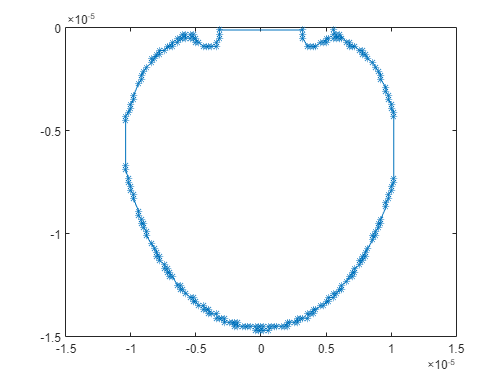

filelist = ["data_along_pit_nearest_neighbor_Pit_4.52.csv";...
            "data_along_pit_nearest_neighbor_Pit_8.01.csv"];
Lpit_active_tot =[];
file = filelist(1);
time = 4.52; 
perforation= 1; % Clean up data if there is perforation
datclean = 0; % Clean up data if there there is unordered data near the pit mouth

Lpit_active_tot =[]; %total active pit surface
n = 1; % number of data plot
nmean = 5;

tiledlayout(1,1);
dat = readtable(file);
plot(dat.x,dat.y,'-*')

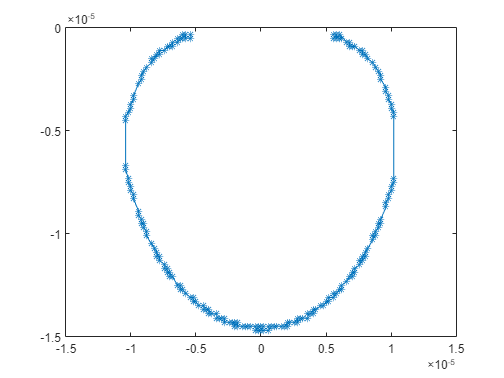

if datclean == true
    %Clean up the data of the excel file:
    idx_front = 1;
    idx_back = 1;
    flipdat = flip(dat(1:idx_front-1,:),1);
    dat_new = [(dat(end-idx_back+1:end,:));dat(idx_front:end-idx_back,:)]; 
    dat_new.l_accum = pitLengthCal(dat_new);
    tiledlayout(1,1);
    plot(dat_new.x,dat_new.y,'-*')
else
    dat_new = dat;
end 

if perforation == true
    %%only when perforation happen:
    idx_front =2;idx_back = 28; %Exclude the passivated area near the pit mouth
    dat_outer = dat_new(idx_front:end-idx_back,:); 
    dat_outer.l_accum = pitLengthCal(dat_outer);
    plot(dat_outer.x,dat_outer.y,'-*')
    dat_new = dat_outer;
end

## Plot simulated data:

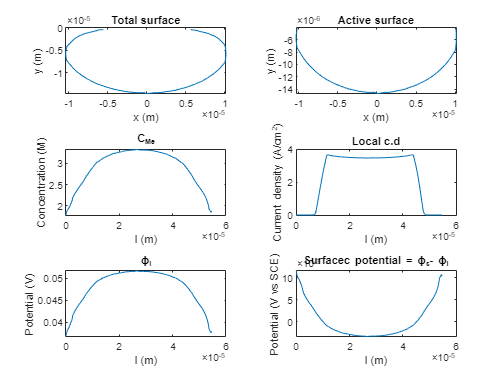


dat = dat_new;
dat.iloc_Acm2 = dat.iloc/10^4;
dat_active = dat(dat.iloc_Acm2>0.2,:);
Lpit_active=pitLengthCal(dat_active);

t = tiledlayout('flow');

% All surface x vs y
ax1 = nexttile;
plot(movmean(dat.x(1:n:end),nmean),movmean(dat.y(1:n:end),nmean),'-')
title(ax1,'Total surface')
ylabel(ax1,'y (m)')
xlabel(ax1,'x (m)')

% Active surface x vs y 
ax2 = nexttile;
plot(movmean(dat_active.x(1:n:end),nmean),movmean(dat_active.y(1:n:end),nmean),'-')
title(ax2,'Active surface')
ylabel(ax2,'y (m)')
xlabel(ax2,'x (m)')

% cMe along all surface
ax3 = nexttile;
plot(movmean(dat.l_accum(1:n:end),nmean),movmean(dat.cMe(1:n:end)/10^3,nmean),'-')
title(ax3,'C_{Me}')
ylabel(ax3,'Concentration (M)')
xlabel('l (m)')

% Local c.d along all surface
ax4 = nexttile;
plot(movmean(dat.l_accum(1:n:end),nmean),movmean(dat.iloc_Acm2(1:n:end),nmean),'-')
title(ax4,'Local c.d')
ylabel(ax4,'Current density (A/cm^2)')
xlabel('l (m)')

% IR drop along all surface
ax5 = nexttile;
plot(movmean(dat.l_accum(1:n:end),nmean),movmean(dat.phil(1:n:end),nmean),'-')
title(ax5,'\phi_l')
ylabel(ax5,'Potential (V)')
xlabel('l (m)')

% Surface potential along all surface
dat.phisminusphil = dat.phis-dat.phil;
ax6 = nexttile;
plot(movmean(dat.l_accum(1:n:end),nmean),movmean(dat.phisminusphil(1:n:end),nmean),'-')
title(ax6,'Surfacec potential = \phi_s- \phi_l')
ylabel(ax6,'Potential (V vs SCE)')
xlabel('l (m)')

% Obtain pit depth and width:
[~,idx1] = min(dat.y); % idx of pit depth
[~,idx2] = min(dat.x);
[~,idx3] = max(dat.x);
pitdepth = abs(dat(idx1,:).y)

pitdepth = 1.4700e-05

pitwidth = dat(idx3,:).x-dat(idx2,:).x

pitwidth = 2.0600e-05

%Export total active pit surface for each time step:
Lpit_active_tot = Lpit_active(end)

Lpit_active_tot = 3.9879e-05

A = [time; Lpit_active(end);dat.phis(1);dat.I(1);pitdepth;pitwidth];
fileID = fopen('activeLength.txt','a');
fprintf(fileID,'%.2f %.8f %.4f %.2f %.8f %.8f\n',A);
fclose(fileID);

function Lpit = pitLengthCal(T)
%   Given the dataset with the order of x,y along the pit surface. 
%   Requirement: T is an ordered dataset with x,y map out the surface of the pit
%   Pit length is calculated based on the Euclidean distance
%   Detailed explanation goes here
x = T.x;
y = T.y;
Lpit=[0];
for i= 1:length(x)-1
    x1 = x(i);
    x2 = x(i+1);
    y1 = y(i);
    y2 = y(i+1);
    l = sqrt((x2-x1)^2+(y2-y1)^2)+Lpit(end);
    Lpit=[Lpit;l];
end
end
%length(Lpit);
%length(x);
   

